clear; clc; close all;

**OFDM Parameters**

nfft = 1024;                    % nfft size equal to number of subcarriers
BW = 1000000000;                % Bandwidth of subcarriers (-F/2 F/2)
M = 256;                          % Baseband modulation order
cp_len = nfft/4;                % Cyclic Prefix length
ofdm_symbols = 20;               % Number of ofdm symbols to transmit
ebno_test = -5:2:35;
symbol_plot = 16;
rep = 4;                        % Repetition of pilots
pilot_index = 112:rep:913;      % Insert a pilot every 3 data sub-carriers
pilot_val = -0.7072+0.7072i;    % Set value of pilot subcarriers
data_index = 1:nfft;            % Index of data subcarriers
% Set 224 zero padded subcarriers: 111 on lower and upper subcarriers
% and 2 on each side of carrier
zp_index = [1:111,913:1024];
no_multi = [1 0 0 0 0 0 0 0];
%multipath1 = [0 0 0 0 0 0.3 0.9 0.4];
multipath1 = [0.5 0.5 0.1 0 0 0 0 0];
data_index([zp_index,pilot_index]) = [];
scs = BW/nfft;
plot_v = 0;
num_data_bits = length(data_index)*ofdm_symbols

num_data_bits = 12000

**Modulate:**

[ofdm_signal,reference_pilot,mod_data,t,t2,freq_signal]=ofdm_transmit(nfft,BW,M,cp_len, ...
    ofdm_symbols,zp_index,pilot_index,0,1,1);

**AWGN Channel + Demodulate:**

Relationship between SNR per bit, $E_b /N_0$ (the ratio of Energy per bit, $E_b$, to the spectral noise density, $N_0$) and SNR (From Matlab AWGN Channel Documentation):

**For Real Signals:**


$$E_b /N_0 \;\left(\textrm{dB}\right)=10\cdot \log_{10} \left(0\ldotp 5\cdot \frac{T_{\textrm{syn}} }{T_{\textrm{samp}} }\right)+\textrm{SNR}\left(\textrm{dB}\right)-10\cdot \log_{10} \left(k\right)$$



$$E_b /N_0 \;\left(\textrm{dB}\right)=10\cdot \log_{10} \left({0\ldotp 5\cdot n}_{\textrm{samp}} \right)+\textrm{SNR}\left(\textrm{dB}\right)-10\cdot \log_{10} \left(k\right)$$



$$\textrm{SNR}\left(\textrm{dB}\right)=E_b /N_0 \;\left(\textrm{dB}\right)-10\cdot \log_{10} \left({0\ldotp 5\cdot n}_{\textrm{samp}} \right)$$


**For Complex Signals**


$$E_b /N_0 \;\left(\textrm{dB}\right)=10\cdot \log_{10} \left(\frac{T_{\textrm{syn}} }{T_{\textrm{samp}} }\right)+\textrm{SNR}\left(\textrm{dB}\right)-10\cdot \log_{10} \left(k\right)$$



$$E_b /N_0 \;\left(\textrm{dB}\right)=10\cdot \log_{10} \left(n_{\textrm{samp}} \right)+\textrm{SNR}\left(\textrm{dB}\right)-10\cdot \log_{10} \left(k\right)$$



$$\textrm{SNR}\left(\textrm{dB}\right)=E_b /N_0 \;\left(\textrm{dB}\right)-10\cdot \log_{10} \left(n_{\textrm{samp}} \right)$$


where $k$ is the number of information bits per symbol (in this case $k=1$ so term goes to zero), $T_{\textrm{syn}}$ is the symbol period and $T_{\textrm{samp}}$ is the sampling period of the signal.

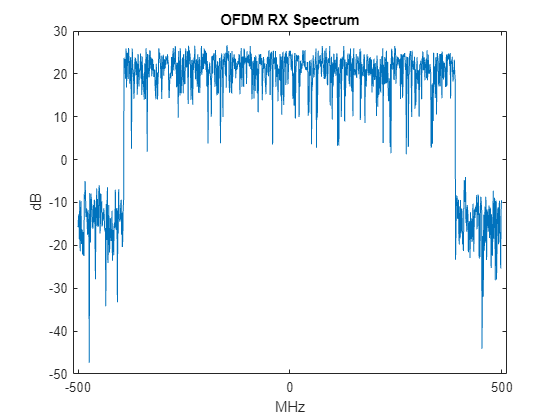

ans = 4×4 table
                           Equalization                           SER    AverageEVM    PeakEVM
    __________________________________________________________    ___    __________    _______

    "No Equalization, No CFO Correction"                           0       1.7685      5.4271 
    "Interpolated Windowed ZF Equalization, No CFO Correction"     0       1.8148      5.5019 
    "No Equalization, CFO Correction"                              0        1.769      5.4353 
    "Interpolated Windowed ZF Equalization, CFO Correction"        0       1.8147      5.5247 


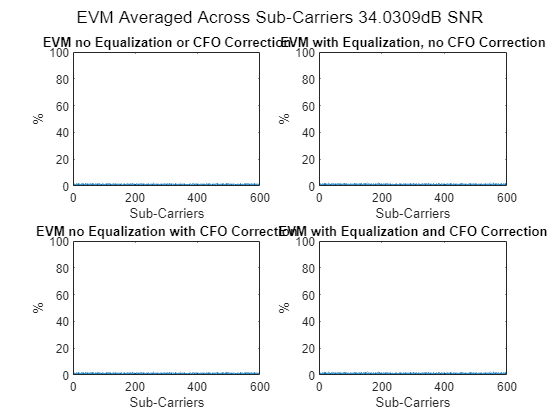

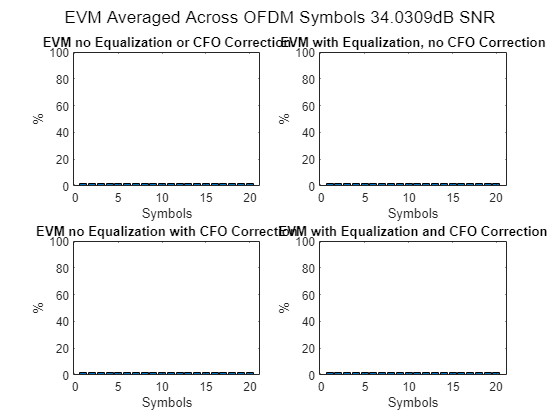

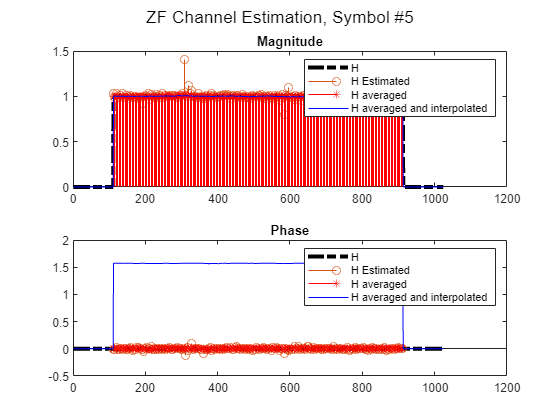

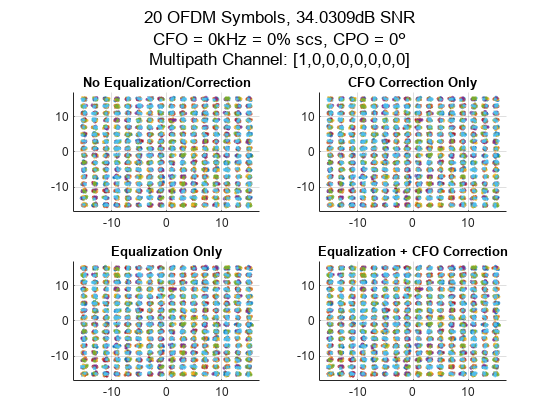

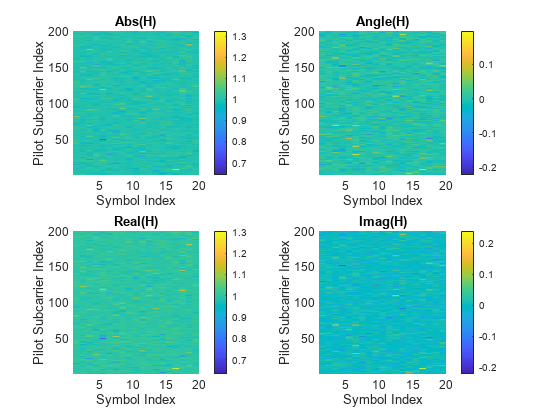

snr_test = ebno_test + 10*log10(log2(M));
ser = [];
sigpower = pow2db(mean(abs(ofdm_signal).^2,'all'));
for i = 1:length(snr_test)
    [ofdm_awgn_signal,nvar] = awgn(ofdm_signal,snr_test(i),sigpower);
    if i == symbol_plot
        plot_v = 1;
    else
        plot_v = 0;
    end
    [dmod,ser(i)]=ofdm_receive(ofdm_awgn_signal,reference_pilot, ...
        nfft,BW,M,cp_len,ofdm_symbols,zp_index,pilot_index,rep,mod_data,[10 7],freq_signal, ...
        0,no_multi,snr_test(i),0,nvar,plot_v,5,ofdm_signal);
end

**AWGN + CFO Channel:**

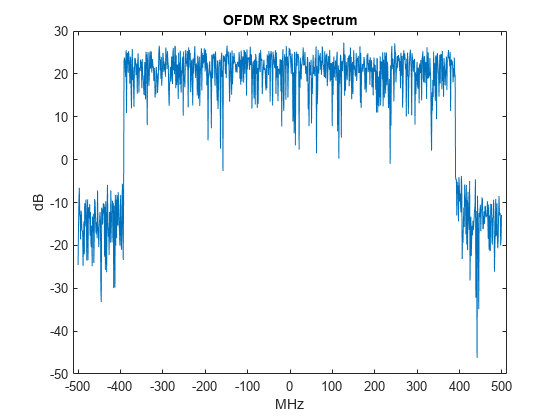

ans = 4×4 table
                           Equalization                              SER        AverageEVM    PeakEVM
    __________________________________________________________    __________    __________    _______

    "No Equalization, No CFO Correction"                             0.99225      135.71      349.77 
    "Interpolated Windowed ZF Equalization, No CFO Correction"       0.69033      71.468      2448.9 
    "No Equalization, CFO Correction"                                0.94767      132.89      325.25 
    "Interpolated Windowed ZF Equalization, CFO Correction"       0.00041667      2.2317      9.5236 


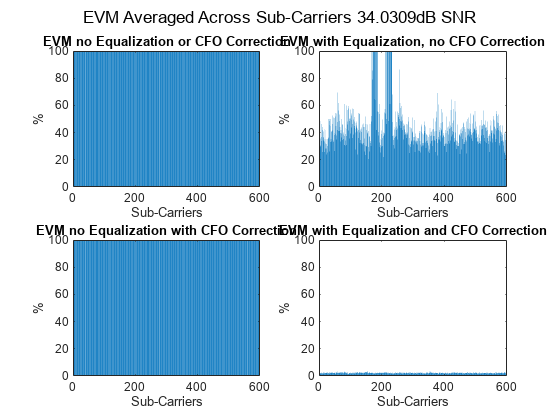

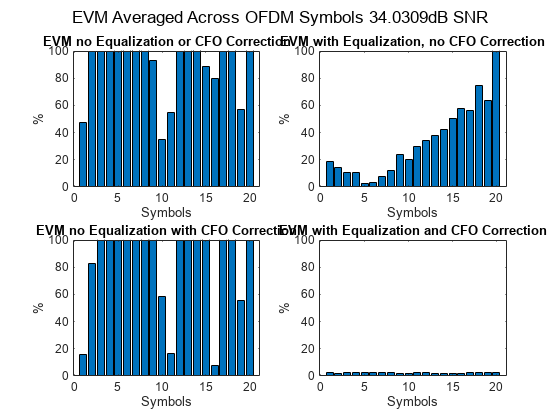

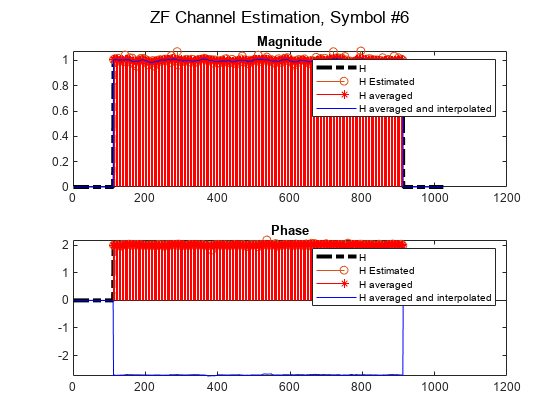

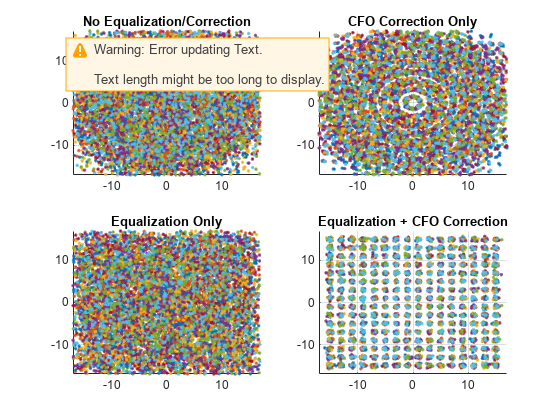

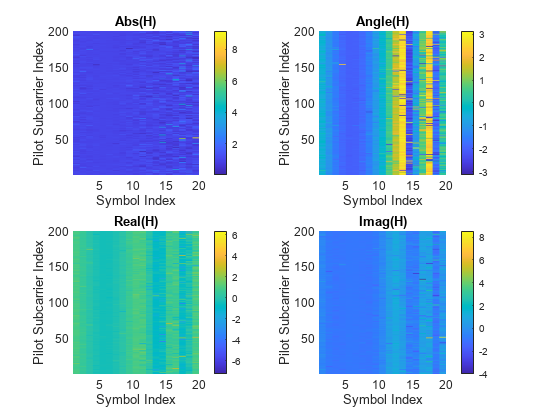

cfo = 100e3;
cfo = linspace(-cfo,cfo,length(t2));
ser1 = [];
sigpower = pow2db(mean(abs(ofdm_signal).^2,'all'));
for i = 1:length(snr_test)
    [ofdm_awgn_signal,nvar]=awgn(ofdm_signal,snr_test(i),'measured');%sigpower);
    ofdm_awgn_signal = exp(1i*2*pi*cfo.*t2)'.*ofdm_awgn_signal;
    if i == symbol_plot
        plot_v = 1;
    else
        plot_v = 0;
    end
    [dmod1,ser1(i)]=ofdm_receive(ofdm_awgn_signal,reference_pilot, ...
        nfft,BW,M,cp_len,ofdm_symbols,zp_index,pilot_index,rep,mod_data,[7 1],freq_signal, ...
        cfo,no_multi,snr_test(i),0,nvar,plot_v,6,ofdm_signal);
end

**AWGN + Multipath Channel:**

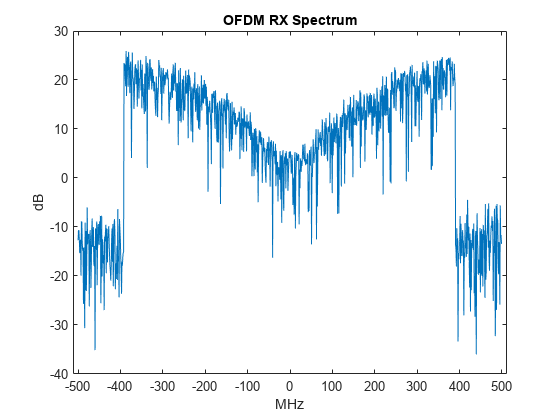

ans = 4×4 table
                           Equalization                              SER        AverageEVM    PeakEVM
    __________________________________________________________    __________    __________    _______

    "No Equalization, No CFO Correction"                               0.993      79.763      146.54 
    "Interpolated Windowed ZF Equalization, No CFO Correction"    0.00041667      2.1879      11.495 
    "No Equalization, CFO Correction"                                0.99292      79.763      146.53 
    "Interpolated Windowed ZF Equalization, CFO Correction"       0.00033333      2.1919      11.423 


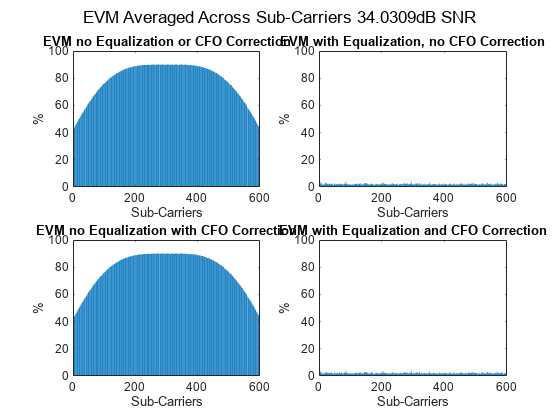

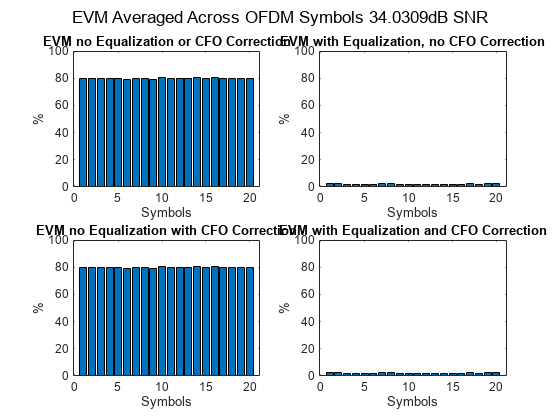

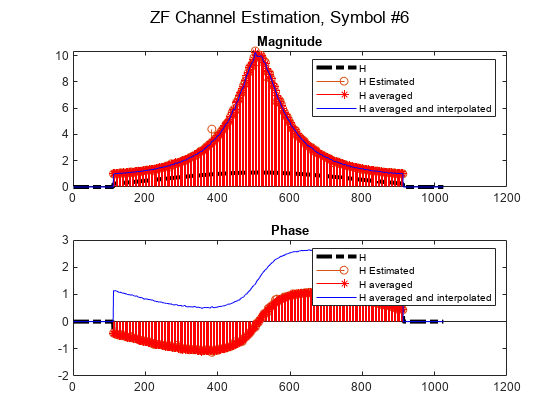

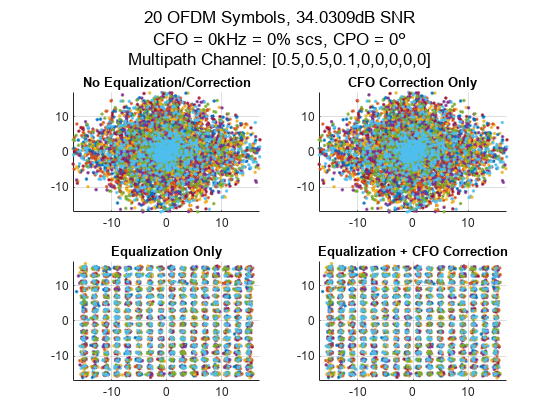

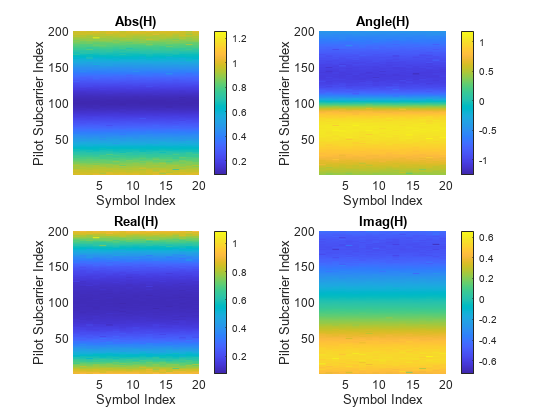

ser2 = [];
sigpower = pow2db(mean(abs(ofdm_signal).^2,'all'));
for i = 1:length(snr_test)
    ofdm_awgn_signal = filter(multipath1,1,awgn(ofdm_signal,snr_test(i),sigpower));
    if i == symbol_plot
        plot_v = 1;
    else
        plot_v = 0;
    end
    [dmod2,ser2(i)]=ofdm_receive(ofdm_awgn_signal,reference_pilot, ...
        nfft,BW,M,cp_len,ofdm_symbols,zp_index,pilot_index,rep,mod_data,[1 7],freq_signal, ...
        0,multipath1,snr_test(i),0,nvar,plot_v,6,ofdm_signal);

end

**AWGN + CPO Channel**

cpo = 3*pi/4;
ser3 = [];
sigpower = pow2db(mean(abs(ofdm_signal).^2,'all'));
for i = 1:length(snr_test)
    [ofdm_awgn_signal,nvar]=awgn(ofdm_signal,snr_test(i),sigpower);
    ofdm_awgn_signal = exp(1i*cpo)'.*ofdm_awgn_signal;
    if i == symbol_plot
        plot_v = 1;
    else
        plot_v = 0;
    end
    [dmod3,ser3(i)]=ofdm_receive(ofdm_awgn_signal,reference_pilot, ...
        nfft,BW,M,cp_len,ofdm_symbols,zp_index,pilot_index,rep,mod_data,[9 9],freq_signal, ...
        0,no_multi,snr_test(i),cpo,nvar,plot_v,6,ofdm_signal);

end

ans = 4×4 table
                           Equalization                           SER    AverageEVM    PeakEVM
    __________________________________________________________    ___    __________    _______

    "No Equalization, No CFO Correction"                           1       184.78      304.51 
    "Interpolated Windowed ZF Equalization, No CFO Correction"     0       1.8164      5.2263 
    "No Equalization, CFO Correction"                              1       184.76      304.41 
    "Interpolated Windowed ZF Equalization, CFO Correction"        0       1.8162      5.1816 


**CFO + CPO + Multipath + Timing Offset + AWGN Channel**

cfo = 50e3;
cpo = 3*pi/4;
ser4 = [];
sigpower = pow2db(mean(abs(ofdm_signal).^2,'all'));
for i = 1:length(snr_test)
    ofdm_awgn_signal = exp(1i*cpo)*exp(1i*2*pi*cfo*t2)'.*ofdm_signal;
    ofdm_awgn_signal = filter(multipath1,1,ofdm_awgn_signal);
    [ofdm_awgn_signal,nvar]=awgn(ofdm_awgn_signal,snr_test(i),sigpower);
    if i == symbol_plot
        plot_v = 1;
    else
        plot_v = 0;
    end
    [dmod4,ser4(i)]=ofdm_receive(ofdm_awgn_signal,reference_pilot, ...
        nfft,BW,M,cp_len,ofdm_symbols,zp_index,pilot_index,rep,mod_data,[3 1],freq_signal, ...
        cfo,multipath1,snr_test(i),cpo,nvar,plot_v,6,ofdm_signal);

end

ans = 4×4 table
                           Equalization                             SER      AverageEVM    PeakEVM
    __________________________________________________________    _______    __________    _______

    "No Equalization, No CFO Correction"                           0.9925      114.26       314.7 
    "Interpolated Windowed ZF Equalization, No CFO Correction"    0.65933      19.515      388.54 
    "No Equalization, CFO Correction"                             0.99117      115.19      307.35 
    "Interpolated Windowed ZF Equalization, CFO Correction"       0.24225      13.464      483.01 


**Theoretical BER Values:**

ebno = -5:35;
[~,theo_ber] = berawgn(ebno,'qam',M);
%[theo_ber,~] = berawgn(ebno,'qam',M);

**Test:**

% snr_convert = convertSNR(ebno_test,'ebno',BitsPerSymbol=log2(M));
% test_ser = [];test_ser1 = [];test_ser2 = [];
% for i=1:length(ebno_test)
%     data_test = randsrc(1024,1000,0:M-1);
%     qam_test = qammod(data_test,M,'UnitAveragePower',true);
%     sigpower = pow2db(mean(abs(qam_test).^2,'all'));
%     qam_test_awgn = awgn(qam_test,snr_test(i),sigpower);
%     qam_rec = qamdemod(qam_test_awgn,M,'UnitAveragePower',true);
%     test_ser = [test_ser symerr(data_test,qam_rec)/numel(data_test)];
%     [tmp_ser1,tmp_ser2] = symerr(data_test,qam_rec);
%     test_ser1 = [test_ser1 tmp_ser1];
%     test_ser2 = [test_ser2 tmp_ser2];
% end


**Plot:**

markersize = 4;
figure()%,semilogy(ebno,theo_ber),hold on
%semilogy(ebno_test,test_ser,'*'),
semilogy(ebno,theo_ber,'k','LineWidth',3),hold on
semilogy(ebno_test,ser,'-o','MarkerSize',markersize)
semilogy(ebno_test,ser1,'-o','MarkerSize',markersize)
semilogy(ebno_test,ser2,'-o','MarkerSize',markersize)
semilogy(ebno_test,ser3,'-o','MarkerSize',markersize)
semilogy(ebno_test,ser4,'-o','MarkerSize',markersize)
ylim([10^-5 1]),grid on,xlim([-5 30])
legend('Theoretical','AWGN','AWGN + CFO','AWGN + Multipath + Offset','AWGN + CPO','AWGN + CFO + CPO + Multipath + Offset')
% legend('Theoretical','AWGN','AWGN + Equalization',['CFO=',num2str(cfo/scs*100),'% No Correction'],['CFO=',num2str(cfo/scs*100),'% with Correction'], ...
%     ['CFO=',num2str(cfo/scs*100),'% with Equalization'],'Multipath no Equalization', ...
%     'Multipath with Equalization')
title(['Probability of Error for OFDM, M=',num2str(M)]),xlabel('SNR'),ylabel('SER')